# Tema 5 (I) - Derivación Numérica

## Ejemplo 1 

Calcular la derivada en todos los puntos por forward difference y por backward difference.

x = [0 0.2 0.4];
y = [0 0.7414 1.3718];
[x;y]

ans =             0          0.2          0.4
            0       0.7414       1.3718


% endevant
fp(1) = (y(2)-y(1))/0.2;     %f'(0)
fp(2) = (y(3)-y(2))/0.2;     %f'(0.2)
%fp(3) = (y(4)-y(3))/0.2;     %f'(0.4)
fp(3) = NaN;

% enrere
fp2(3) = (y(3)-y(2))/0.2;     %f'(0.4)
fp2(2) = (y(2)-y(1))/0.2;     %f'(0.2)
%fp2(1) = (y(1)-y(0))/0.2;     %f'(0)
fp2(1) = NaN;

[x;y;fp;fp2]

ans =             0          0.2          0.4
            0       0.7414       1.3718
        3.707        3.152          NaN
          NaN        3.707        3.152


## Ejemplo 2

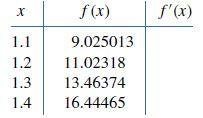

Calcular la derivada en todos los puntos con una fórmula de orden el más alto posible orden, O(h) i O(h^2)

h = 0.05;
x = [1.1:h:1.4]; y = exp(2*x);
n = length(x);
% O(h^2)
for k=2:n-1
    fp3(k) = (y(k+1)-y(k-1))/(2*h); 
end
fp3(1) = (-3*y(1)+4*y(2)-y(3))/(2*h);
fp3(n) = (3*y(n)-4*y(n-1)+y(n-2))/(2*h)

fp3 =        17.985       19.982       22.083       24.406       26.972       29.809       32.788


ERRORES. Los datos se corresponden a la función $y=e^{2x}$ la derivada es $y'=2e^{2x}$. Crear tabla para visualitzar error absoluto en las fórmulas usadas

valor_exacte = 2*exp(2*x)

valor_exacte =         18.05       19.948       22.046       24.365       26.927       29.759       32.889


error_abs = abs(fp3-valor_exacte)

error_abs =      0.064898     0.033264     0.036762     0.040629     0.044902     0.049624      0.10178


xs = -log10(2*error_abs./abs(valor_exacte))    % xifres significatives

xs =        2.1432       2.4769       2.4769       2.4769       2.4769       2.4769       2.2084


## Ejemplo 3

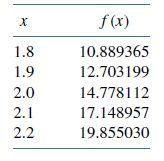

Calcular f'(2.0) con h=0.1 y h=02. Los datos son de f(x)=x*e^x, calcular los errores absolutos. Crear tabla para visualitzar error absoluto en las fórmulas usadas

#### Ejercicio - fullMN_lab8

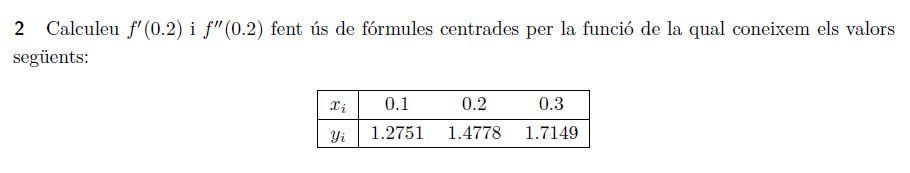

clearvars
h = 0.1; x = [0.1:h:0.3]; y = [1.2751, 1.4778, 1.7149];
fprimera = (y(3)-y(1))/(2*h)

fprimera =         2.199

fsegona = (y(3)-2*y(2)+y(1))/(h^2)

fsegona =          3.44

#### Ejercicio - fullMN_lab8

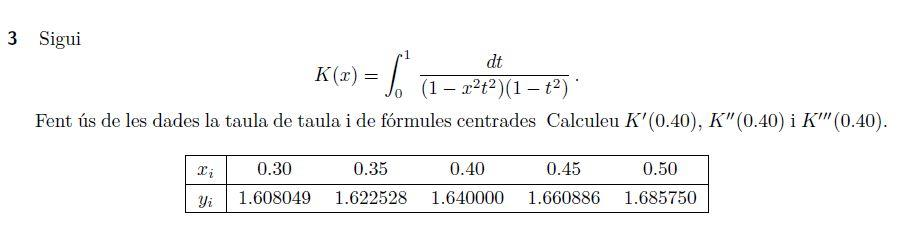

# Error en las fórmulas de diferenciación numérica 

#### Ejercicio - fullMN_lab8

f=@(x)log(x);
k=0:14;
h=1./10.^k;
for k=1:15
fp(k)=(f(2+h(k))-f(2))/h(k);
end
er = abs(fp-0.5);
format short G
taula=[h; fp; er]' 

taula =             1      0.40547     0.094535
          0.1       0.4879     0.012098
         0.01      0.49875    0.0012458
        0.001      0.49988   0.00012496
       0.0001      0.49999     1.25e-05
        1e-05          0.5     1.25e-06
        1e-06          0.5   1.2494e-07
        1e-07          0.5   1.3031e-08
        1e-08          0.5   3.0387e-09
        1e-09          0.5    4.137e-08


A medida que aumentem el h, l'error es fa mes petit

% formula centrada
f=@(x)log(x);
k=0:14;
h=1./10.^k;
for k=1:15
    fp(k)=(f(2+h(k))-f(2-h(k)))/(2*h(k));
end
er = abs(fp-0.5);
format short G
taula=[h; fp; er]' 

taula =             1      0.54931     0.049306
          0.1      0.50042   0.00041729
         0.01          0.5   4.1667e-06
        0.001          0.5   4.1667e-08
       0.0001          0.5   4.1683e-10
        1e-05          0.5   8.8267e-12
        1e-06          0.5   1.4378e-11
        1e-07          0.5   2.6318e-10
        1e-08          0.5   3.0387e-09
        1e-09          0.5    4.137e-08


# Extrapolació de Richardson

% Exemple apunts de classe
clearvars;
format short g, format compact
f=@(x)log(x); 
a=2; ve=1/2;
n = 6;
hk = 1:n;
h(1:n) = 1 ./2.^hk;

%% Error en derivació numèrica
% Exemple apunts de classe
for k=1:n
    fp(k) = (f(a+h(k))-f(a-h(k)))/(2*h(k));
    end
er = abs(fp-ve);
taula = [h(1:n);fp;er]'

taula =           0.5      0.51083     0.010826
         0.25      0.50263    0.0026289
        0.125      0.50065   0.00065257
       0.0625      0.50016   0.00016286
      0.03125      0.50004   4.0696e-05
     0.015625      0.50001   1.0173e-05



T1(1) = 0;
T1(2:n) = (4*fp(2:n)-fp(1:n-1))/3;
er2 = abs(T1-ve); er2(1) = 0;
taula1 = [h(1:n);fp;T1;er2]'    % extrapolació de richardson 1 per aumentar l'ordre de la formula

taula1 =           0.5      0.51083            0            0
         0.25      0.50263       0.4999    0.0001034
        0.125      0.50065      0.49999   6.1898e-06
       0.0625      0.50016          0.5    3.828e-07
      0.03125      0.50004          0.5   2.3863e-08
     0.015625      0.50001          0.5   1.4904e-09



T2(1:2) = 0;
T2(3:n) = (4^2*T1(3:n)-T1(2:n-1))/(4^2-1);
er3 = abs(T2-ve); er3(1:2) = 0;
taula2 = [h(1:n);fp;T1;T2;er3]' % richardson 2

taula2 =           0.5      0.51083            0            0            0
         0.25      0.50263       0.4999            0            0
        0.125      0.50065      0.49999          0.5   2.9086e-07
       0.0625      0.50016          0.5          0.5   4.3263e-09
      0.03125      0.50004          0.5          0.5    6.679e-11
     0.015625      0.50001          0.5          0.5   1.0411e-12


## Resultats

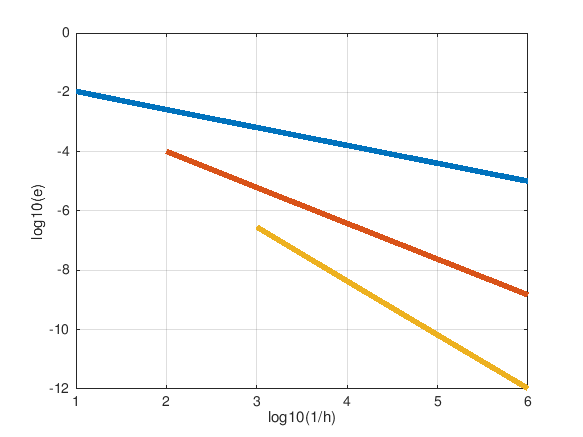

% Gràfic
figure(1)
plot(hk,log10(er),hk,log10(er2),hk,log10(er3),'Linewidth',4); grid;
xlabel('log10(1/h)');ylabel('log10(e)');

# Approximate Derivatives with diff

Consultar la ayuda de Matlab para la instrucción diff y trasladar ejemplo función seno. 

Consultar la ayuda de Matlab para la instrucción diff y trasladar ejemplo función seno. 

Use the `diff` function to approximate partial derivatives with the syntax `Y = diff(f)/h`, where `f` is a vector of function values evaluated over some domain, `X`, and `h` is an appropriate step size.

For example, the first derivative of `sin(x)` with respect to `x` is `cos(x)`, and the second derivative with respect to `x`is `-sin(x)`. You can use `diff` to approximate these derivatives.

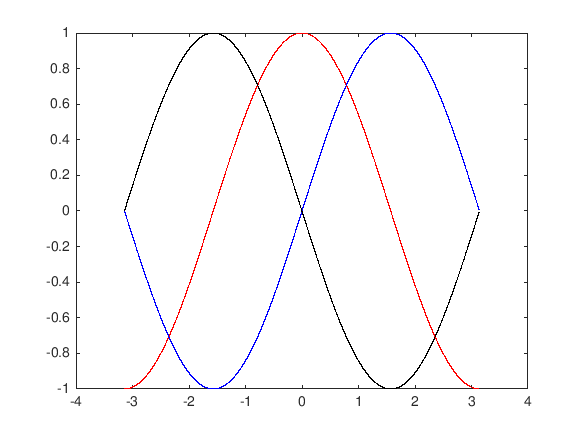

h = 0.001;       % step size
X = -pi:h:pi;    % domain
f = sin(X);      % range
Y = diff(f)/h;   % first derivative
Z = diff(Y)/h;   % second derivative
plot(X(:,1:length(Y)),Y,'r',X,f,'b', X(:,1:length(Z)),Z,'k')

#### Document preparat per Mª Àngela Grau Gotés (prof. responsable MN)